### Modelo ajuste Step

clearvars;
close all

Datos=xlsread('step.xlsx');

t=Datos(:,1);
U=Datos(:,2);
Y=Datos(:,3);

subplot(2,1,1)
plot(t,U,'* k','MarkerSize',4)
ylabel('Entrada')
grid on
subplot(2,1,2)
plot(t,Y,'o b','MarkerSize',4)
ylabel('Salida')
xlabel('Tiempo')
hold on
grid on

% Seleccionando na=3, nb=4, d=1
s=length(Y);

X=[-[0;Y(1:s-1)],-[0;0;Y(1:s-2)],-[0;0;0;Y(1:s-3)],[0;U(1:s-1)],[0;0;U(1:s-2)],[0;0;0;U(1:s-3)],[0;0;0;0;U(1:s-4)]];
%Matriz de covarianzas
Q=X'*X;

%Vector de parámetros
Theta=inv(Q)*X'*Y;

z=tf('z',0.04);

Gpm=((Theta(4)*z^3+Theta(5)*z^2+Theta(6)*z+Theta(7))/(z^3+Theta(1)*z^2+Theta(2)*z+Theta(3)))*(z^(-1))

Gpm =
 
  0.055 z^3 + 0.02255 z^2 + 0.04212 z + 0.07212
  ---------------------------------------------
     z^4 + 0.41 z^3 - 0.2644 z^2 - 0.1695 z
 
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


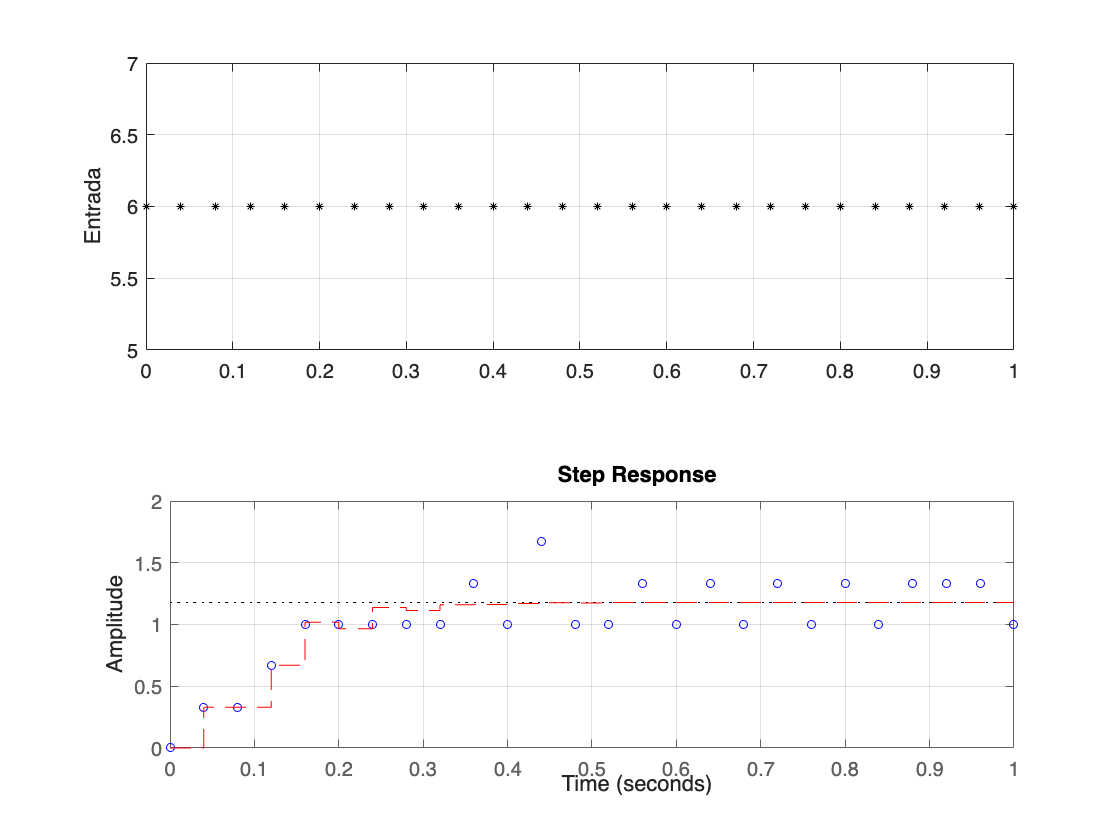

% z^-1 ya que a=t/T
step(Gpm*6,'r--',max(t))
grid on

Ym=step(Gpm*6,max(t));


%Validación del modelo
Sy=sum((Y-mean(Y)).^2)

Sy = 3.3110

Sr=sum((Y-Ym).^2)

Sr = 0.7424

R2=(Sy-Sr)/Sy

R2 = 0.7758

gcz =
 
              0.03921 z^10 - 0.1 z^9 + 0.05659 z^8 + 0.03335 z^7 - 0.02606 z^6 - 0.009457 z^5 + 0.006386 z^4
  ----------------------------------------------------------------------------------------------------------------------
  0.055 z^11 - 0.1931 z^10 + 0.2687 z^9 - 0.1648 z^8 - 0.07946 z^7 + 0.2795 z^6 - 0.2285 z^5 + 0.0599 z^4 + 0.002717 z^3
 
Sample time: 0.04 seconds
Discrete-time transfer function.


### Modelo ajuste PRBS

clear all
close all

Datos=xlsread('PRBS');

t=Datos(:,1);
U=Datos(:,2);
Y=Datos(:,3);

subplot(2,1,1)
plot(t,U,'* k','MarkerSize',4)
ylabel('Entrada')
grid on
subplot(2,1,2)
plot(t,Y,'o b','MarkerSize',4)
ylabel('Salida')
xlabel('Tiempo')
hold on
grid on

% Seleccionando na=3, nb=4, d=1
s=length(Y);

X=[-[0;Y(1:s-1)],-[0;0;Y(1:s-2)],-[0;0;0;Y(1:s-3)],[0;U(1:s-1)],[0;0;U(1:s-2)],[0;0;0;U(1:s-3)],[0;0;0;0;U(1:s-4)]];
%Matriz de covarianzas
Q=X'*X;

%Vector de parámetros
Theta=inv(Q)*X'*Y;

z=tf('z',0.150);

Gpm=((Theta(4)*z^3+Theta(5)*z^2+Theta(6)*z+Theta(7))/(z^3+Theta(1)*z^2+Theta(2)*z+Theta(3)))*(z^(-1))

Gpm =
 
  0.2464 z^3 - 0.01969 z^2 - 0.01228 z - 0.01892
  ----------------------------------------------
    z^4 - 0.2778 z^3 - 0.03327 z^2 - 0.1347 z
 
Sample time: 0.15 seconds
Discrete-time transfer function.
Model Properties


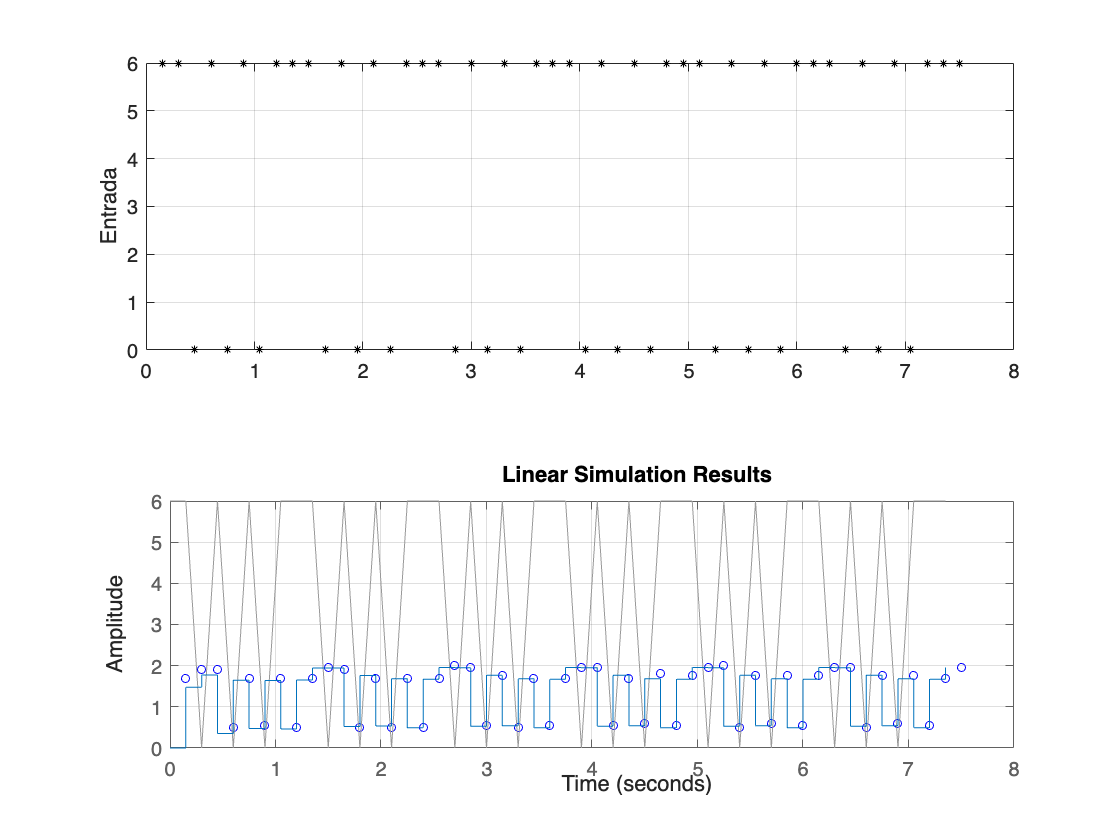

% z^-1 ya que a=t/T
lsim(Gpm,U);
grid on

Ym=lsim(Gpm,U);


%Validación del modelo
Sy=sum((Y-mean(Y)).^2)

Sy = 19.2492

Sr=sum((Y-Ym).^2)

Sr = 3.2071

R2=(Sy-Sr)/Sy

R2 = 0.8334

k=1; %para sistema causal
T=0.15;
z=tf('z',T);
tz=(1/(1-z^-1)-1/(1-exp(-T)*z^-1))*(1-z^-1)*(z^-k);
gcz=1/Gpm*tz/(1-tz)

gcz =
 
                0.1393 z^10 - 0.4372 z^9 + 0.4851 z^8 - 0.2307 z^7 + 0.07436 z^6 - 0.04706 z^5 + 0.01614 z^4
  -------------------------------------------------------------------------------------------------------------------------
  0.2464 z^11 - 0.9366 z^10 + 1.304 z^9 - 0.7636 z^8 + 0.1528 z^7 - 0.03855 z^6 + 0.04625 z^5 - 0.008315 z^4 - 0.002268 z^3
 
Sample time: 0.15 seconds
Discrete-time transfer function.
